% kappa_ext = 1.2323e6;
% kappa_int = .22653e6;
kappa_ext = 1.271e6;
kappa_int = .2e6;
kappa_tot = kappa_ext + kappa_int; %kappa_int = 0.2265MHz. These values correspond to ng = 0 and phi = 0 for Jules' sample in March 2021 small fridge
% kerr = 0;
omega_0 = 5.7851e9; % in Hz. 
kerr = -.44e6;
detunings = linspace(980e6, 1000e6, 1000);
% drive_freq = 6.767e9;
% detunings = drive_freq - omega_0 + detunings;
detunings_spacing_1 = mean(abs(diff(detunings)));
number_detunings_2 = 300;
h = 6.626e-34; % just h, not hbar since omega_0 is in Hz
plot_figures = 1;

fridge_attenuation = 108; % for TWPA pump line : 50dB intentional, 20dB dir coupler coupling, 17dB - dir coupler isolation, 18dB - circulator isolation
% pump_line_attenuation = 87; % this was used on December 8th. this was wrong.
% fridge_attenuation = pump_line_attenuation;
power_input_start_dBm = -10 - fridge_attenuation; 
power_input_stop_dBm = 10 - fridge_attenuation; % 81dB is approx fridge attenuation. 
power_input_start_watts = 1e-3.*10.^(power_input_start_dBm/10);
power_input_stop_watts = 1e-3.*10.^(power_input_stop_dBm/10);

% power_input_in_watts = linspace(power_input_start_watts, power_input_stop_watts, 5);
% power_input_in_dBm = 10*log10(power_input_in_watts/1e-3);

power_input_in_dBm = linspace(power_input_start_dBm, power_input_stop_dBm, 100);
power_input_in_watts = 1e-3.*10.^(power_input_in_dBm/10);

power_input_in_numbers = power_input_in_watts/h/omega_0;
kerr = kerr/1e6;
kappa_ext = kappa_ext /1e6;
kappa_tot = kappa_tot/ 1e6;
detunings = detunings/ 1e6;
power_input_in_numbers = power_input_in_numbers/1e6;
[detunings_array, power_input_array] = meshgrid(detunings, power_input_in_numbers);
amp_roots = zeros([size(detunings_array),3]);

for i = 1: size(detunings_array,1)
    for j = 1: size(detunings_array,2)
        amp_roots(i,j,:) = roots([kerr^2, -2*kerr.*detunings_array(i,j), (detunings_array(i,j).^2 + kappa_tot^2 / 4),...
            -kappa_ext * power_input_array(i,j)]);
    end
end

amp_roots(imag(amp_roots) ~=0) = 0;
main_s11 = zeros([size(detunings_array)]);
first_zero_root_1 = zeros(size(detunings_array,1),1);
first_zero_root_3 = zeros(size(detunings_array,1),1);

detunings_array_reps = repmat(detunings_array, [1, 1, 3]);
s11 = ((detunings_array_reps - kerr .* amp_roots) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((detunings_array_reps - kerr .* amp_roots) -1i*kappa_tot/2);
s11(amp_roots == 0) = 5;
for i = 1: size(detunings_array,1)
    if ~all(amp_roots(i,:,3)) 
        first_zero_root_3(i) = find(amp_roots(i,:,3) == 0, 1) - 1;
        first_zero_root_1(i) = length(amp_roots(i,:,1)) - find(flip(amp_roots(i,:,1) ~= 0),1) + 1;
        main_s11(i,:) = [s11(i,1:first_zero_root_3(i),3), s11(i,first_zero_root_3(i) + 1: first_zero_root_1(i), 1), s11(i,first_zero_root_1(i) + 1: end, 3)];
    else
        main_s11(i,:) = s11(i,:,3);
    end
end
[max_phase_shift, max_phase_shift_index] = max(abs(diff(wrapTo180(180/pi*(angle(main_s11))), 1, 2)),[],2);
max_detunings = detunings(max_phase_shift_index);
detunings_2 = zeros(1, number_detunings_2);
[detunings_array_fine, power_input_array_fine] = meshgrid(detunings_2 , power_input_in_numbers);
for i = 1: length(power_input_in_numbers)
    detunings_array_fine(i, :) = linspace(max_detunings(i) - detunings_spacing_1/1e6, max_detunings(i) + detunings_spacing_1/1e6, number_detunings_2);
end
detunings_spacing_2 = mean(abs(diff(detunings_array_fine(1,:))))*1e6;
amp_roots_fine = zeros([size(detunings_array_fine), 3]);

for i = 1: size(detunings_array_fine,1)
    for j = 1: size(detunings_array_fine,2)
        amp_roots_fine(i,j,:) = roots([kerr^2, -2*kerr.*detunings_array_fine(i,j), (detunings_array_fine(i,j).^2 + kappa_tot^2 / 4),...
            -kappa_ext * power_input_array_fine(i,j)]);
    end
end
amp_roots_fine(imag(amp_roots_fine) ~=0) = 0;

detunings_array_fine_reps = repmat(detunings_array_fine, [1, 1, 3]);
s11_fine = ((detunings_array_fine_reps - kerr .* amp_roots_fine) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((detunings_array_fine_reps - kerr .* amp_roots_fine) -1i*kappa_tot/2);
s11_fine(amp_roots_fine == 0) = 5;

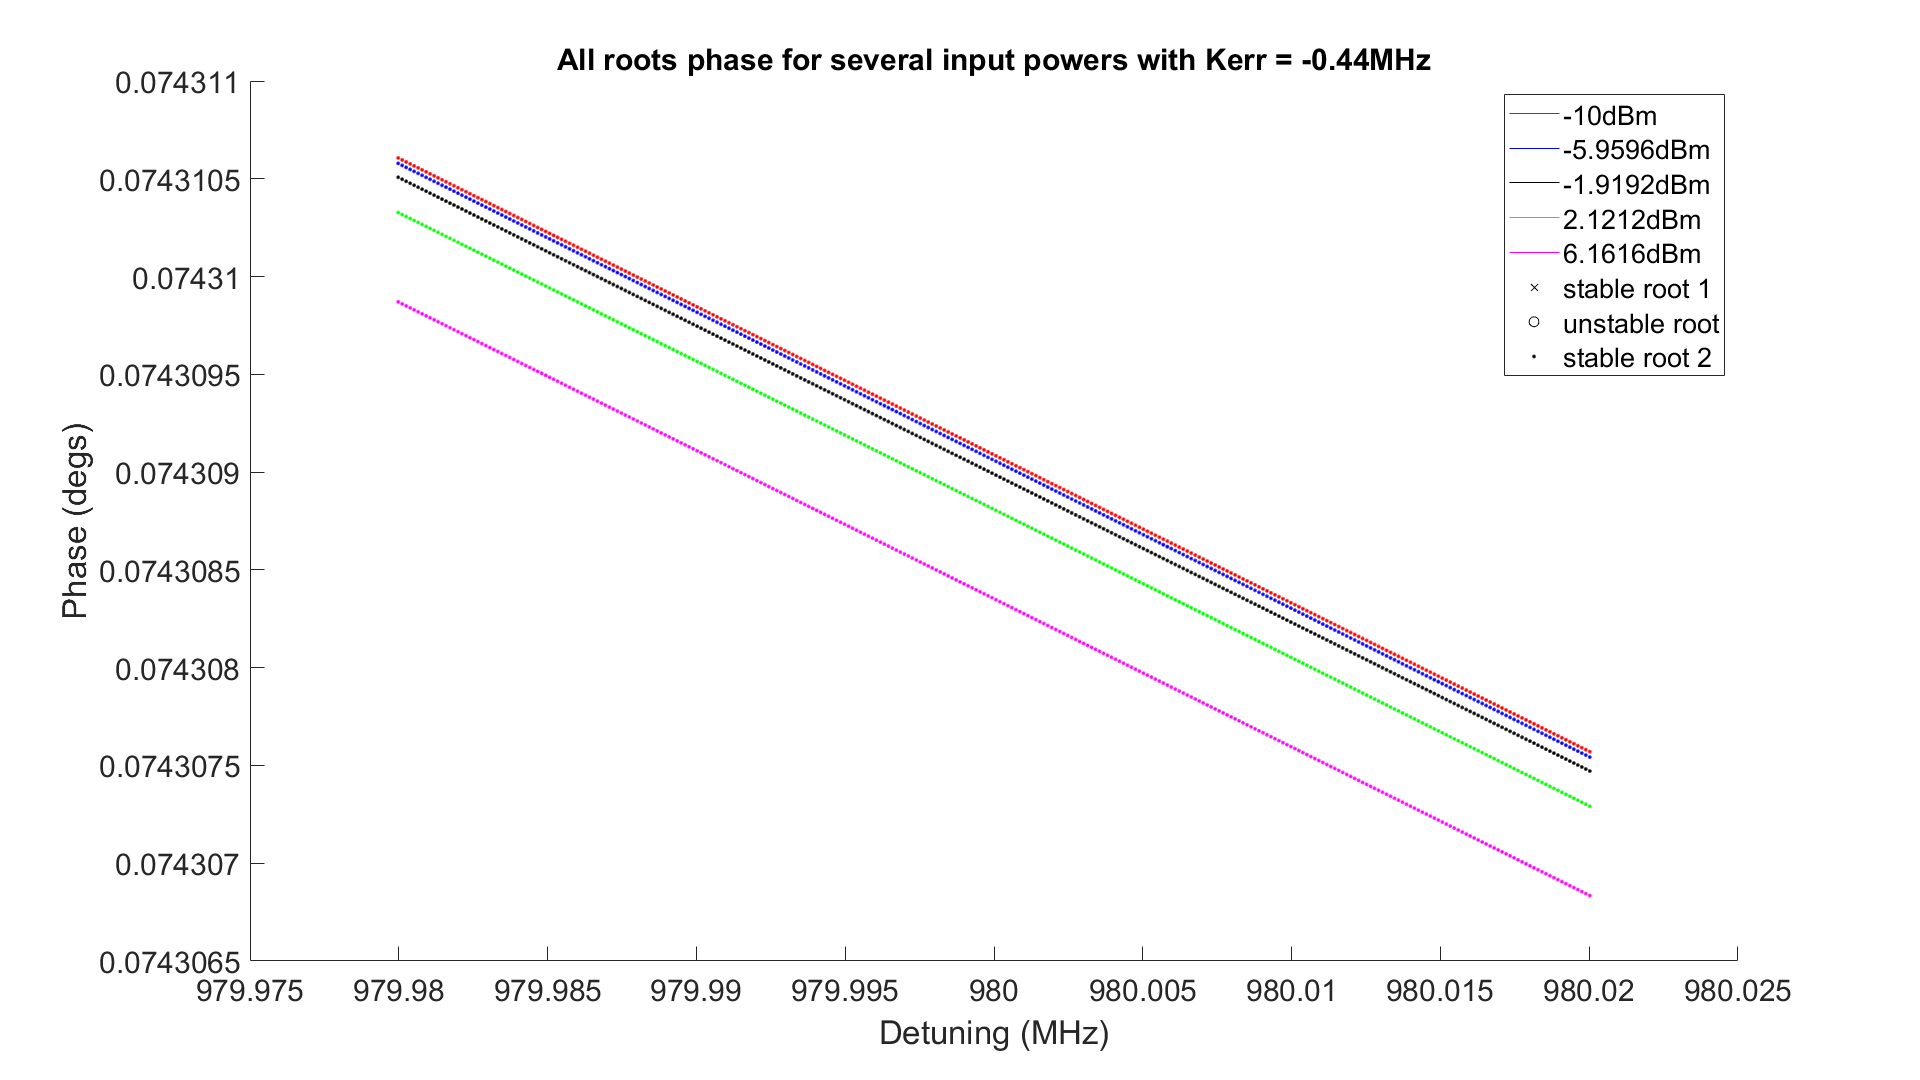

figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<100
        detunings_array_1_fine = detunings_array_fine(i,:);
        s11_root_1_temp = s11_fine(i,:,1);
        detunings_array_1_fine (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2_fine = detunings_array_fine(i,:);
        s11_root_2_temp = s11_fine(i,:,2);
        detunings_array_2_fine (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3_fine = detunings_array_fine(i,:);
        s11_root_3_temp = s11_fine(i,:,3);
        detunings_array_3_fine (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(detunings_array_1_fine, wrapTo180(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 1'])
        hold on
        plot(detunings_array_2_fine, wrapTo180(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 2'])
        plot(detunings_array_3_fine, wrapTo180(angle(s11_root_3_temp)*180/pi),root_3_color_prop)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 3'])
        xlabel('Detuning (MHz)')
        ylabel('Phase (degs)')
        title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    qw = zeros(8,1);
    qw(1) = plot(nan, nan, 'r');hold on
    qw(2) = plot(nan, nan, 'b');
    qw(3) = plot(nan, nan, 'k');
    qw(4) = plot(nan, nan, 'g');
    qw(5) = plot(nan, nan, 'm');
    qw(6) = plot(nan, nan, 'kx');
    qw(7) = plot(nan, nan, 'ko');    
    qw(8) = plot(nan, nan, 'k.');
    legend (qw, [num2str(power_input_in_dBm(1) +  fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) +  fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) +  fridge_attenuation) 'dBm'],...
        [num2str(power_input_in_dBm(61) +  fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(81) +  fridge_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')
    hold off

check_detuning_number = 501

check_power_input = 3

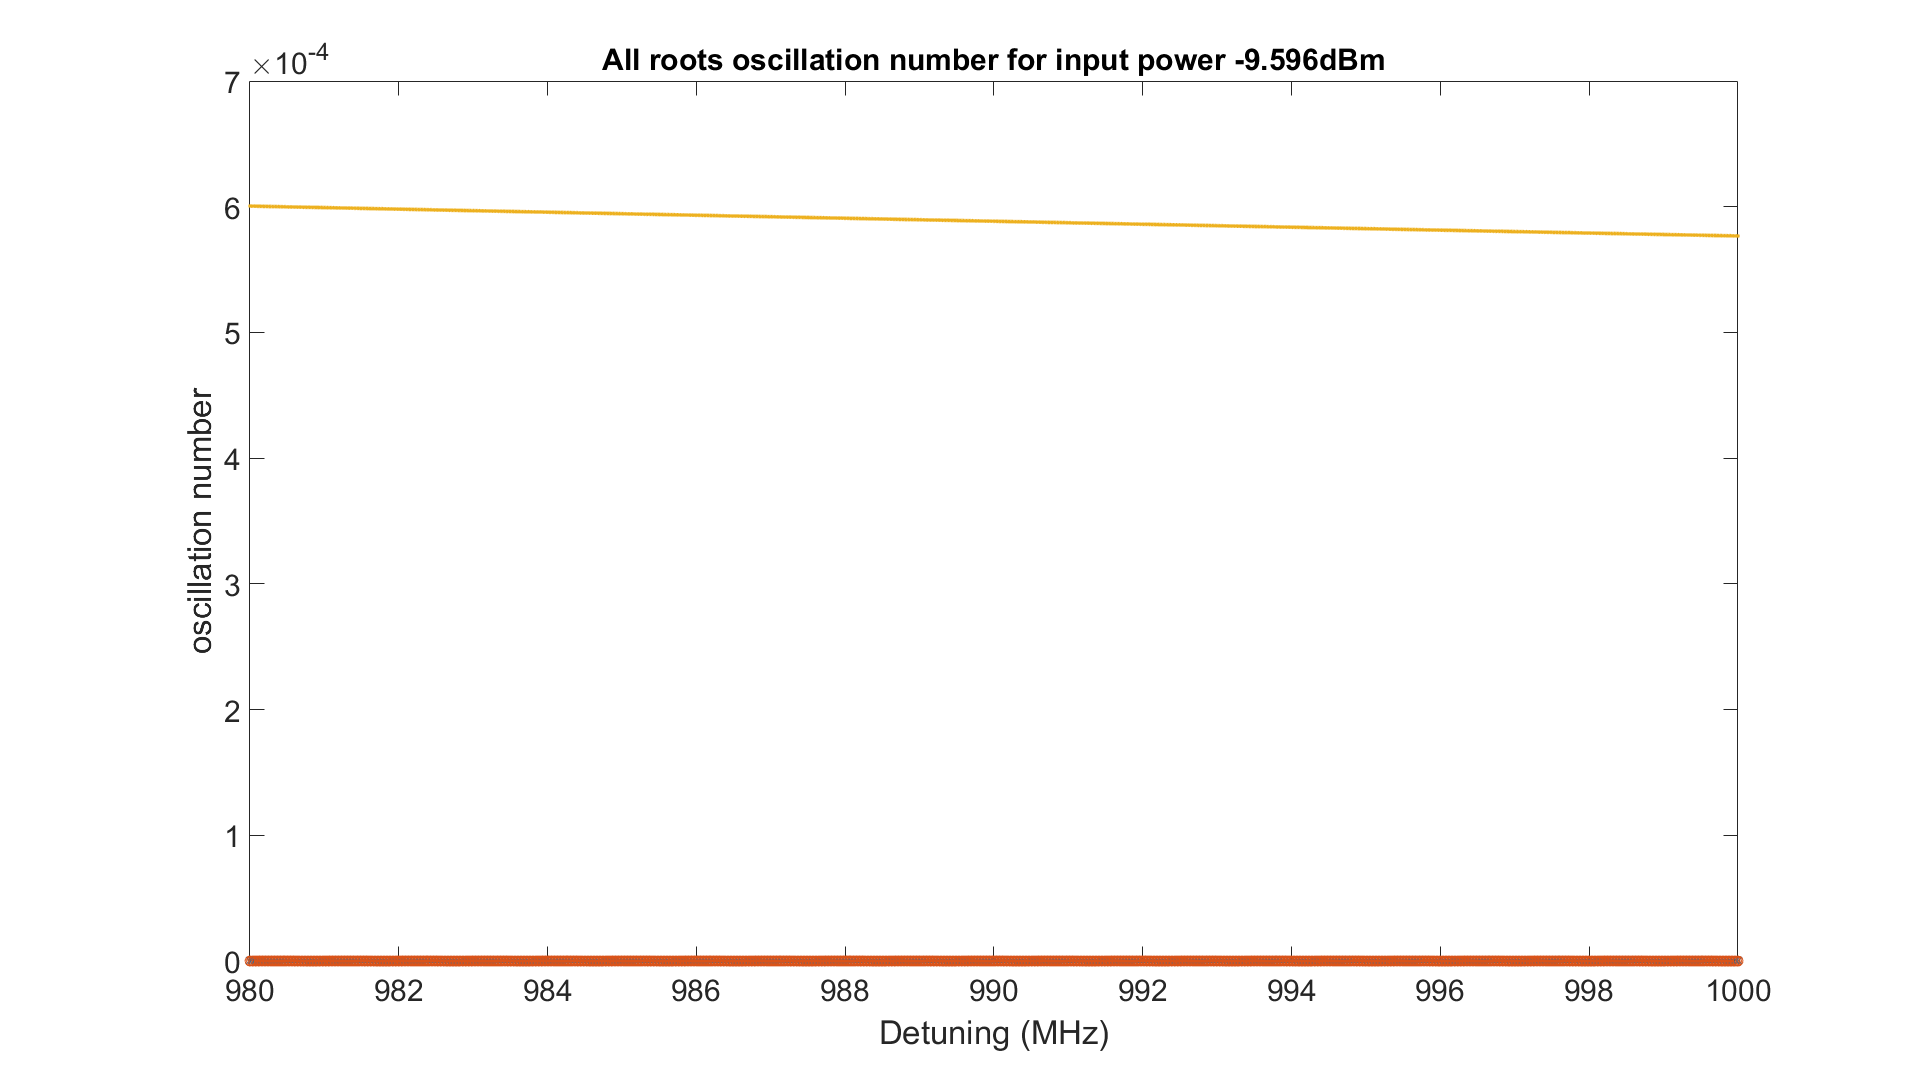

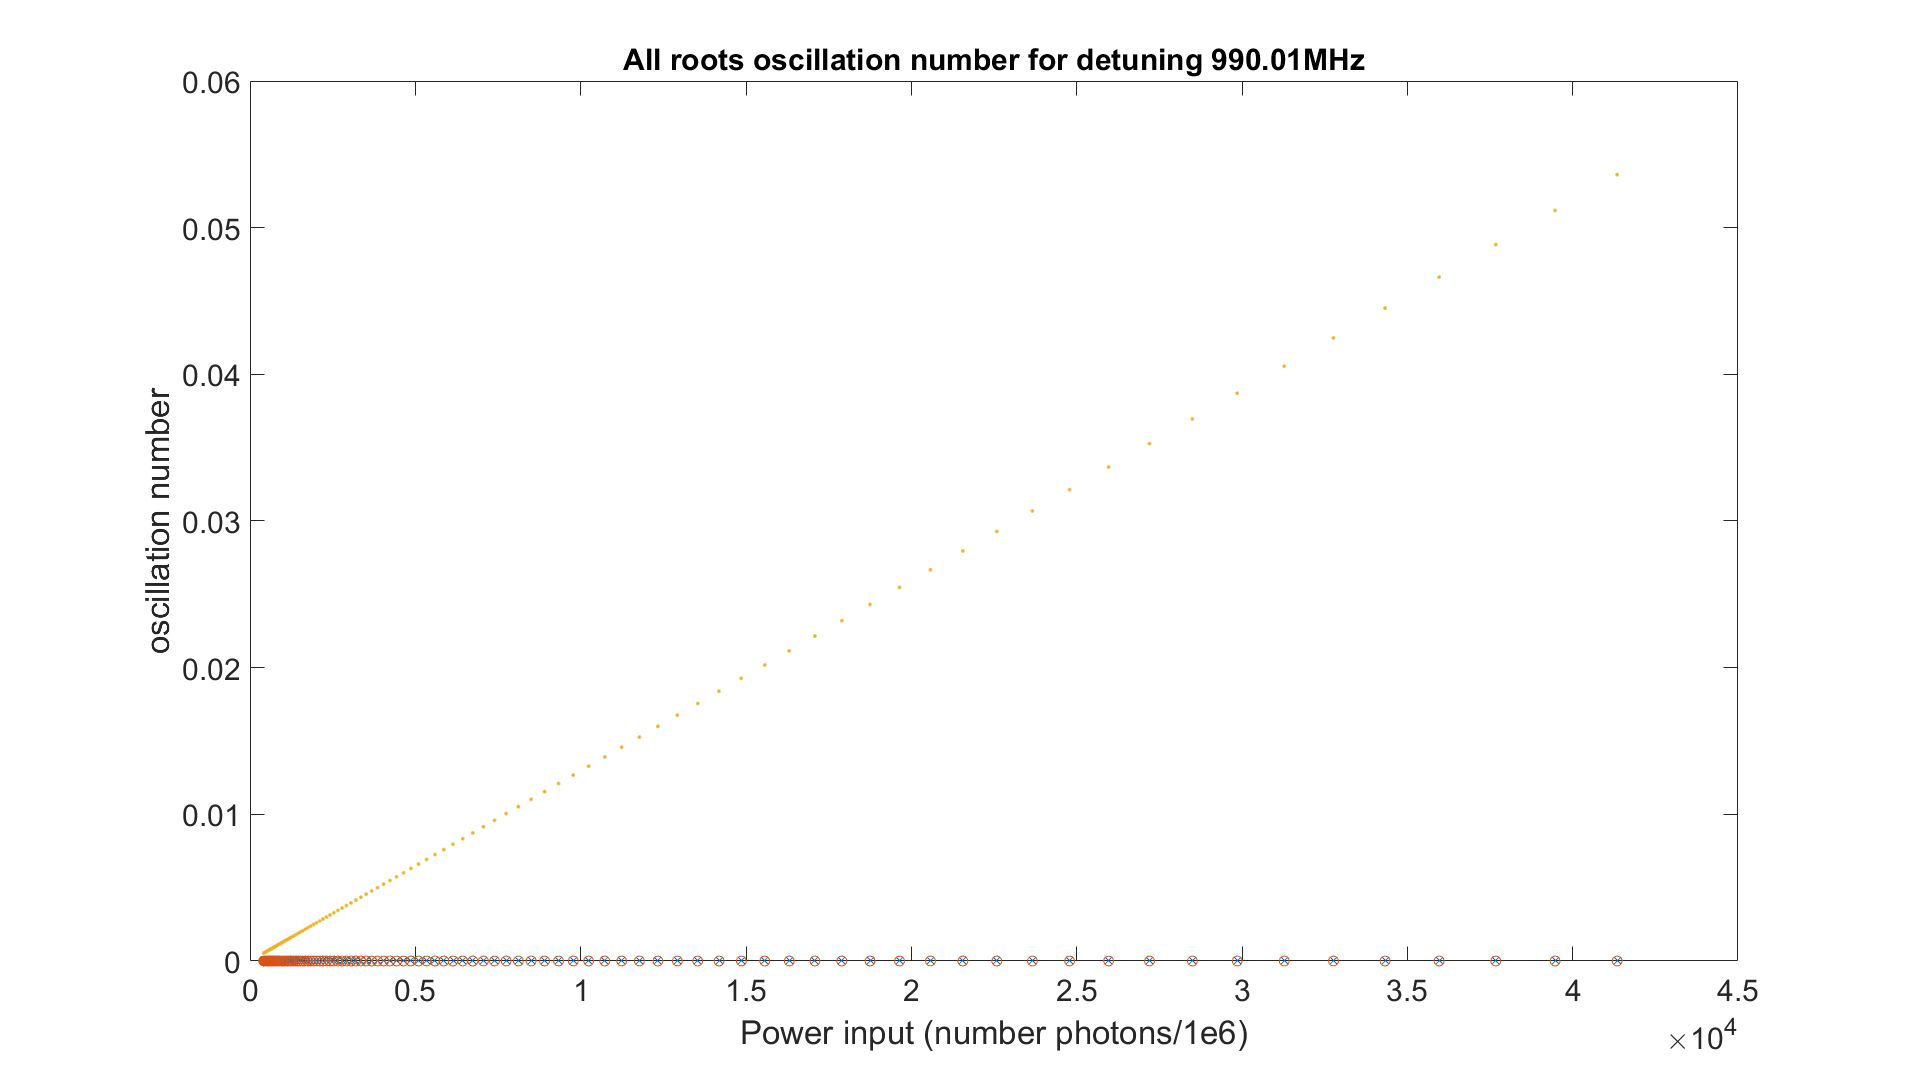

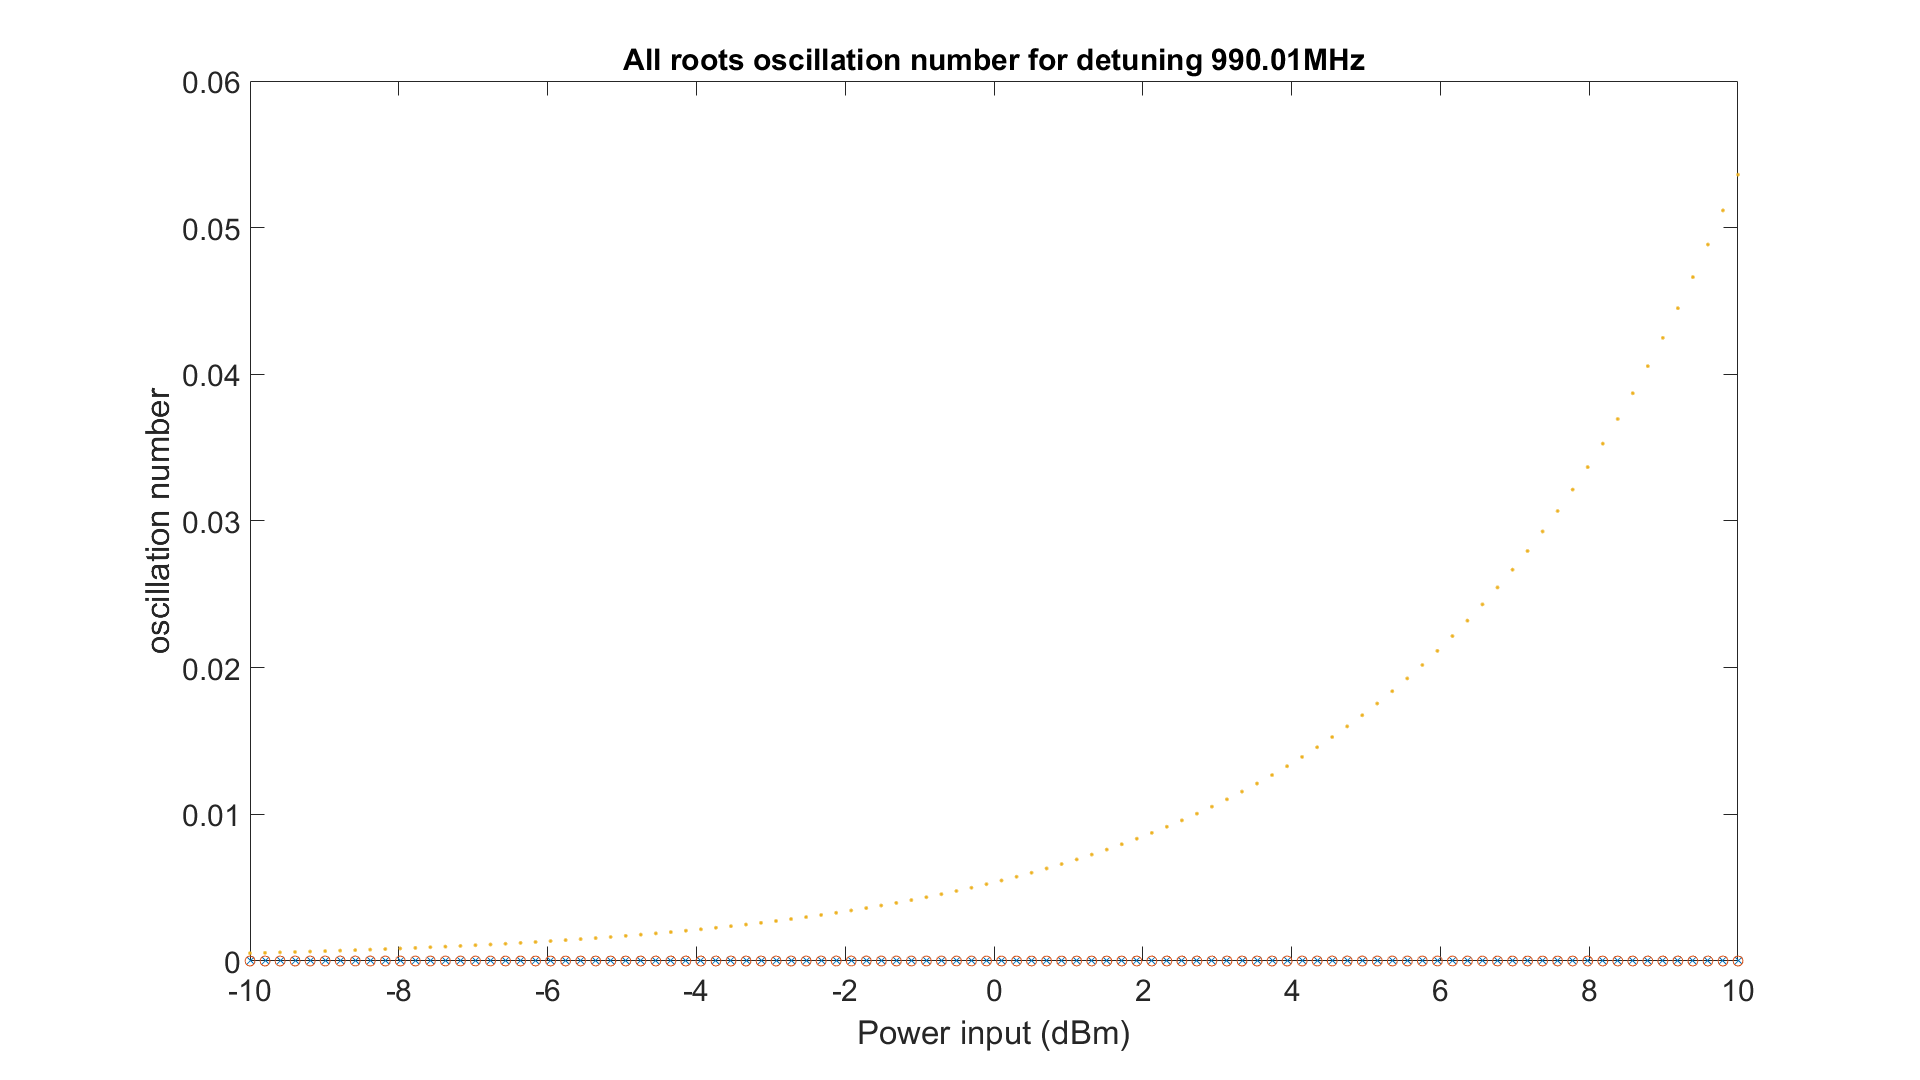

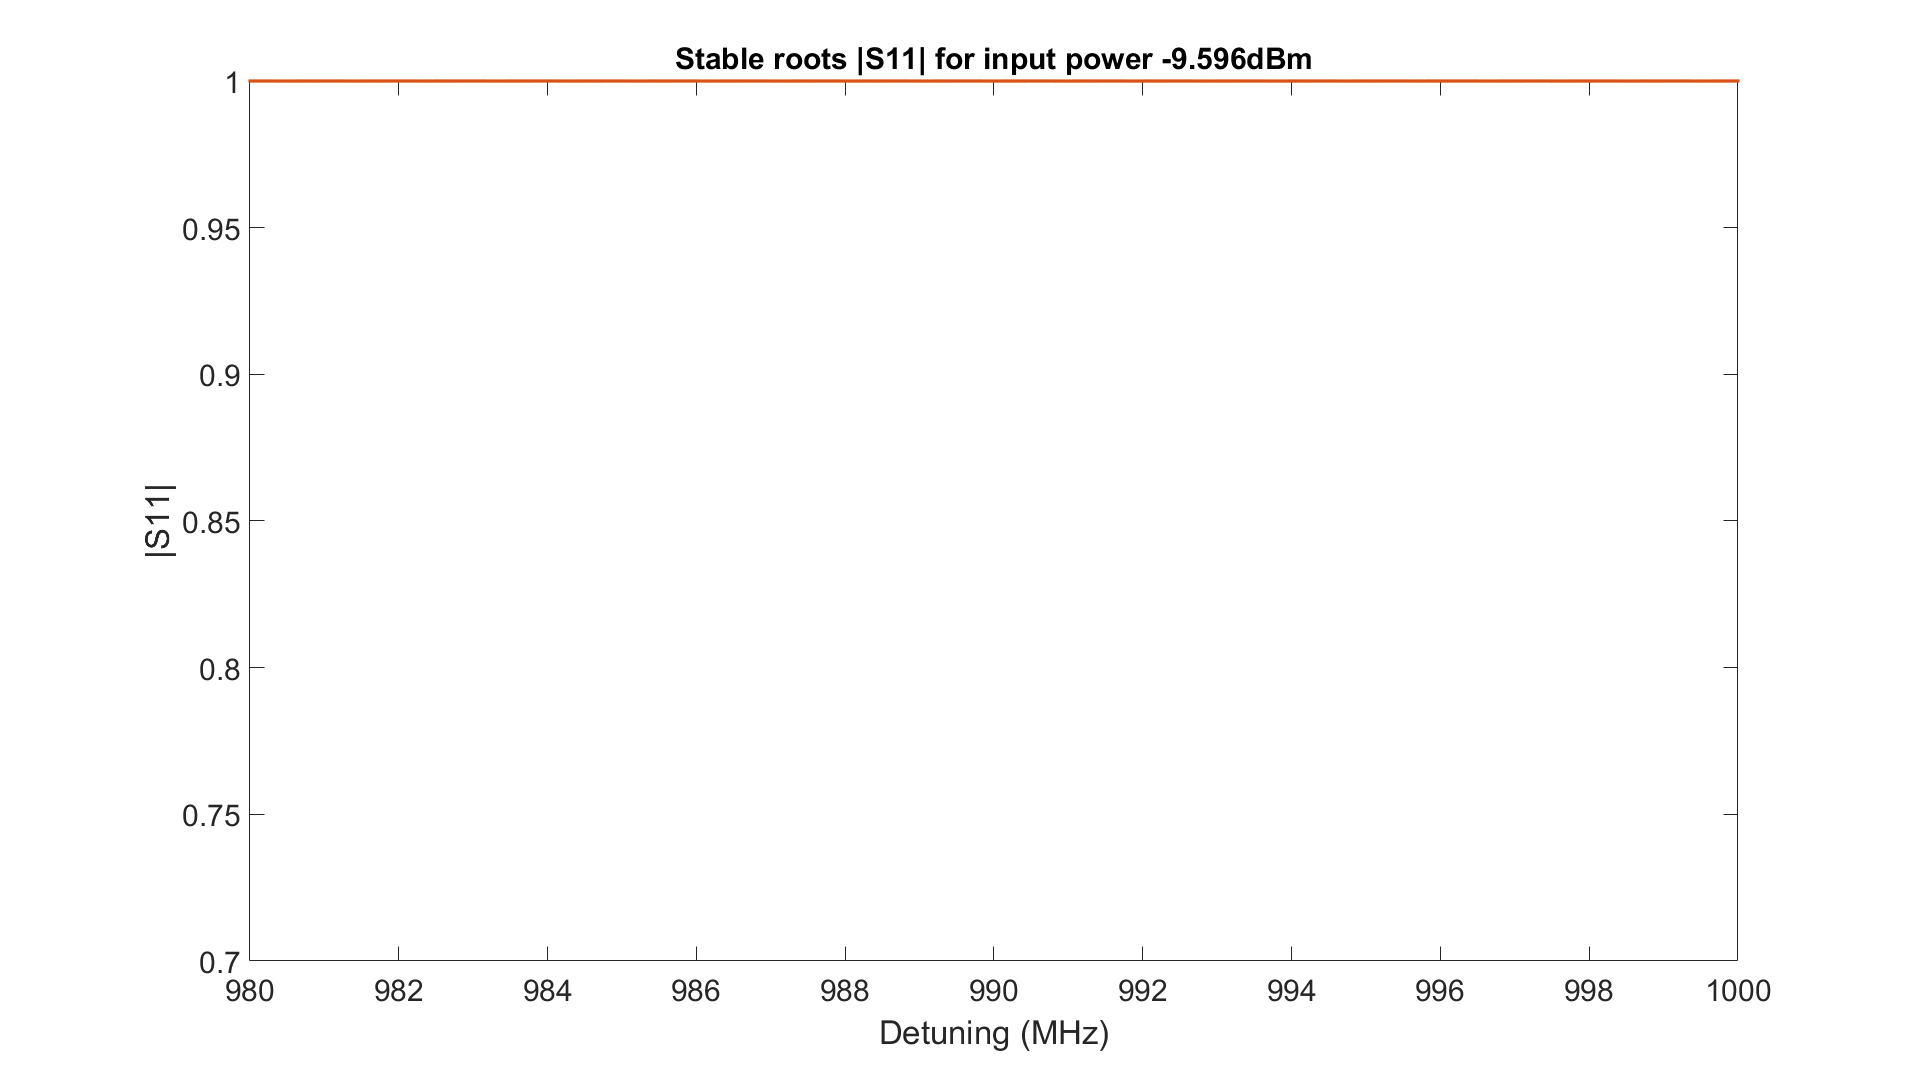

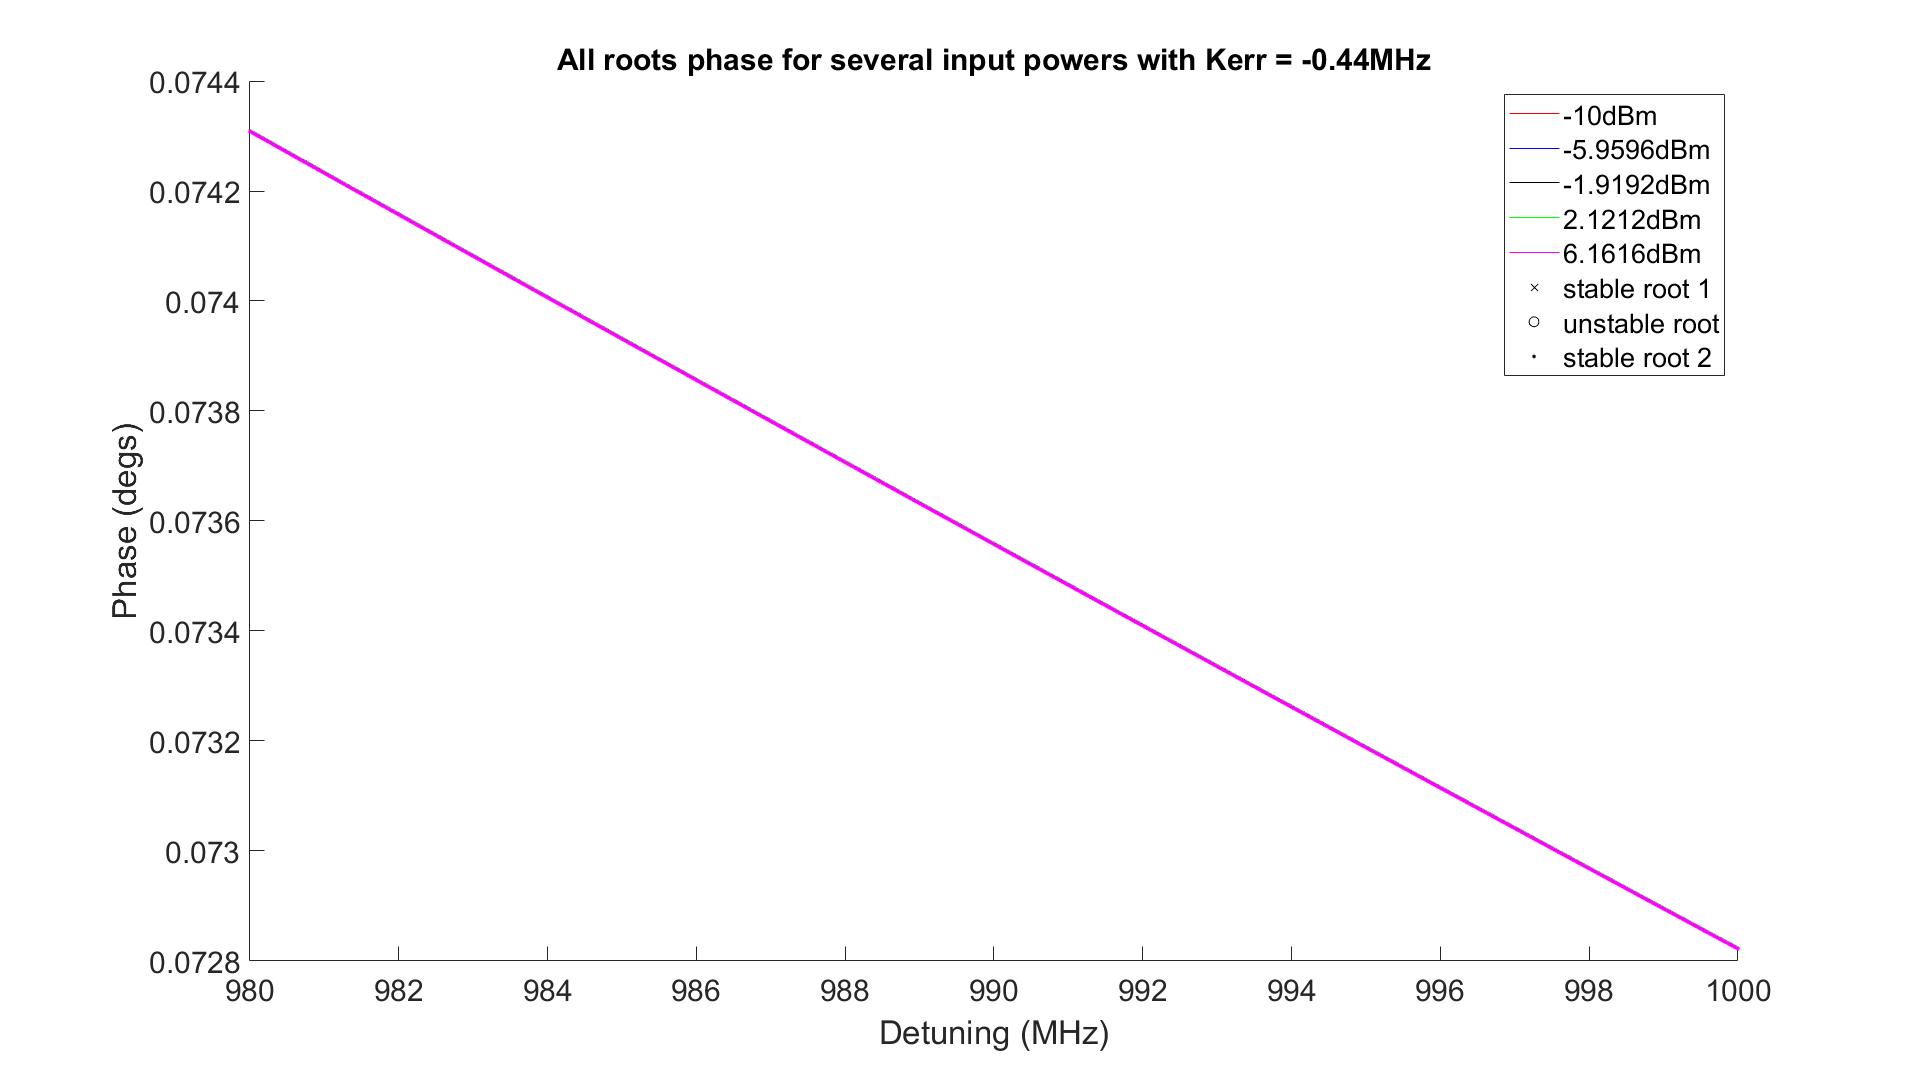

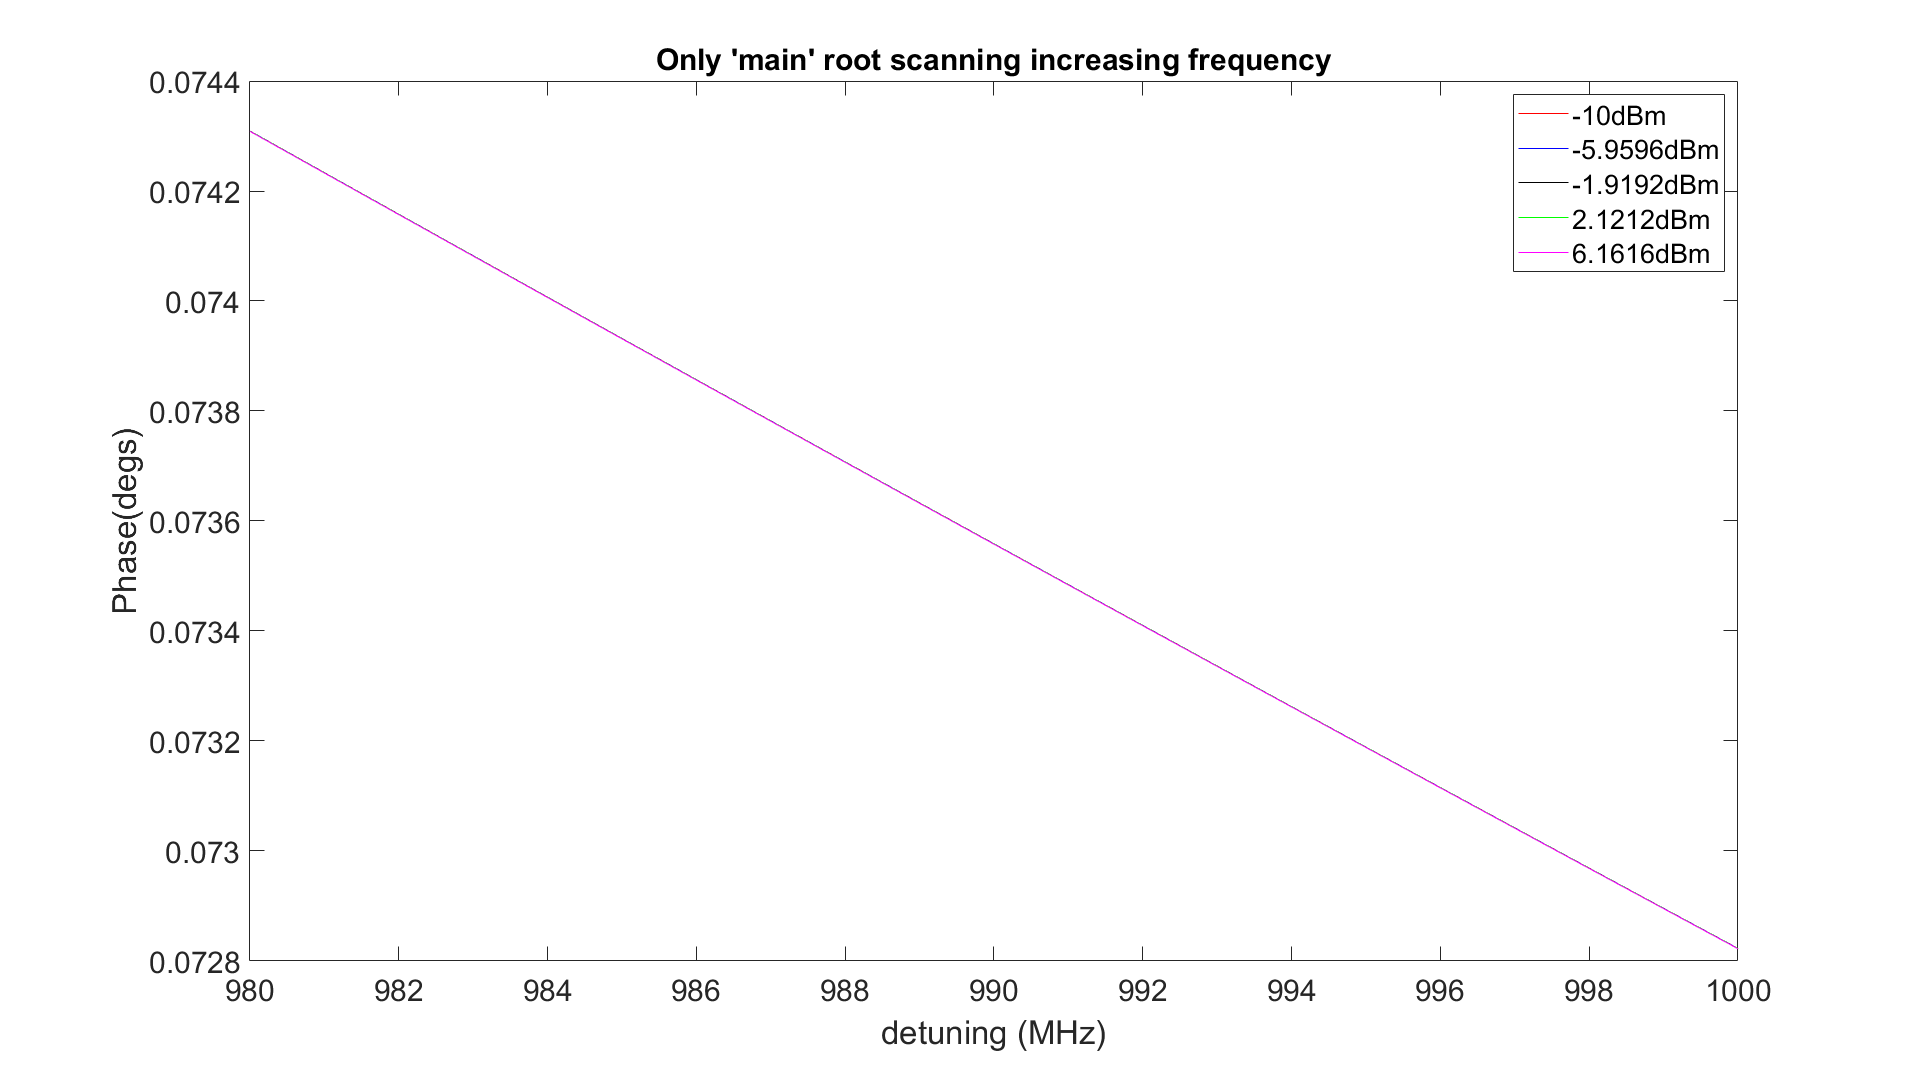

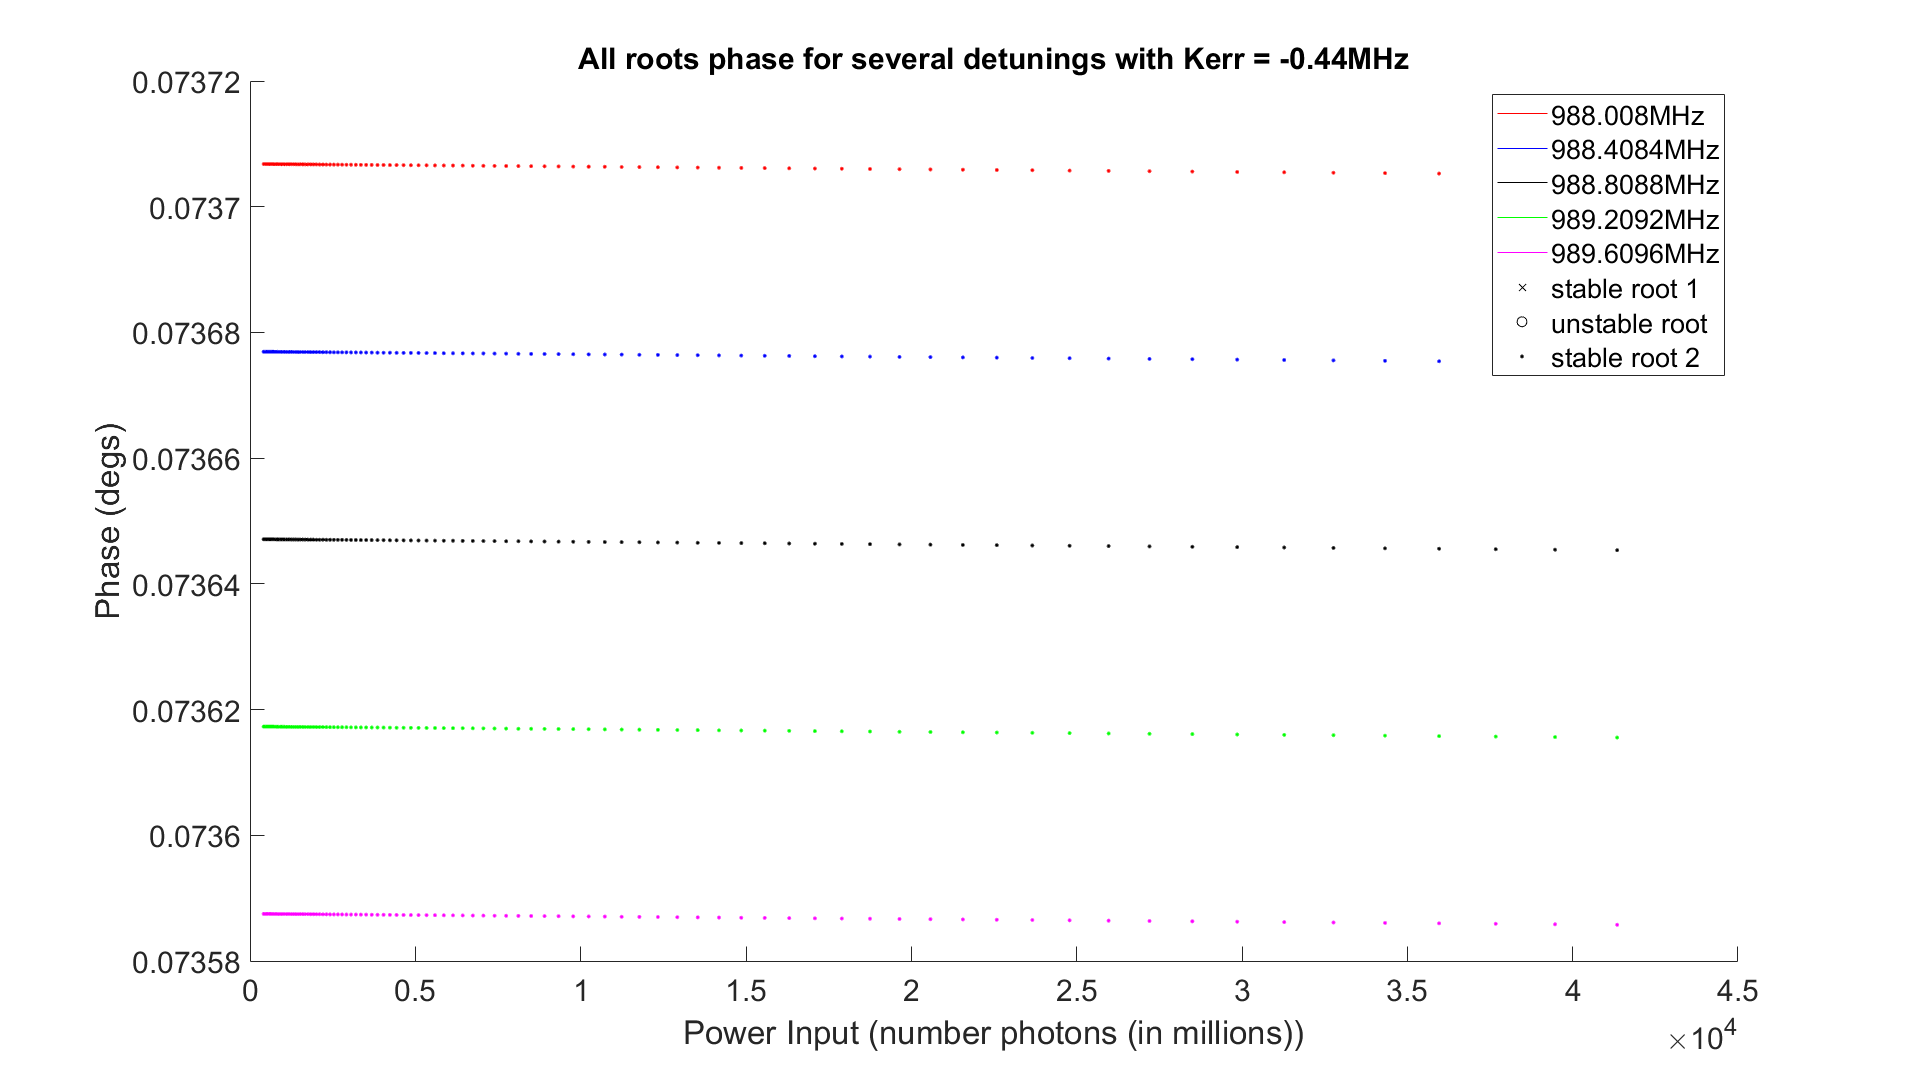

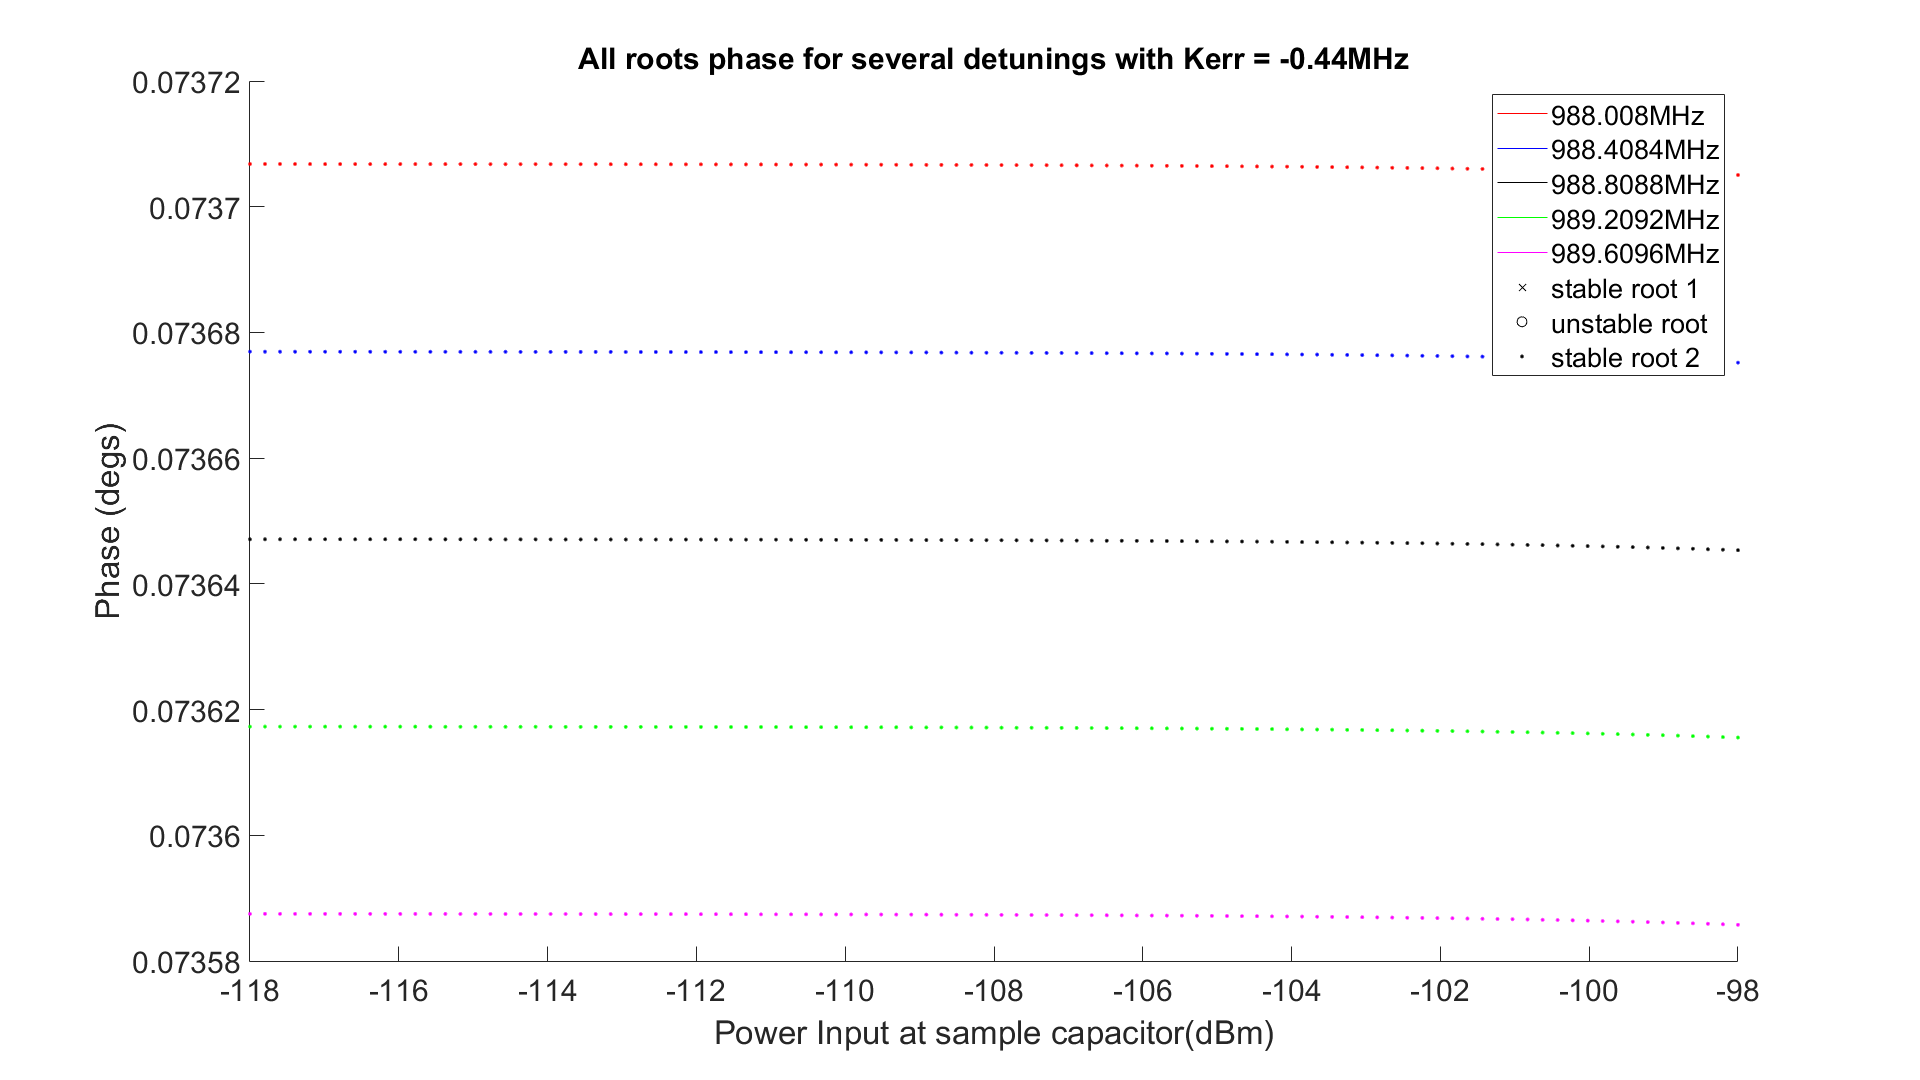

if plot_figures == 1
    % check_detuning_number = randi(length(detunings)/2)
    % check_power_input = randi(length(power_input_in_numbers))
    check_detuning_number = 501
    check_power_input = 3
    % amp_roots(check_power_input,check_detuning_number,:)
    % check_value = kerr^2 .* amp_roots(check_power_input,check_detuning_number,:).^3 - 2*kerr.*detunings_array(check_power_input,check_detuning_number) .* amp_roots(check_power_input,check_detuning_number,:).^2  +...
    %     (detunings_array(check_power_input,check_detuning_number)^2 + kappa_tot^2/4) .* amp_roots(check_power_input,check_detuning_number,:) -...
    %     kappa_ext * power_input_array(check_power_input,check_detuning_number)
        
    % i = randi(100)
    % figure
    % plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,1))
    % xlabel('Detuning (Hz)')
    % ylabel('oscillation number')
    % title(['1st root oscillation number for input power ' num2str(power_input_in_dBm(i)) 'dBm'])
    % 
    % figure
    % plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,2))
    % xlabel('Detuning (Hz)')
    % ylabel('oscillation number')
    % title(['2nd root oscillation number for input power ' num2str(power_input_in_dBm(check_power_input)) 'dBm'])
    % 
    % figure
    % plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,3))
    % xlabel('Detuning (Hz)')
    % ylabel('oscillation number')
    % title(['3rd root oscillation number for input power ' num2str(power_input_in_dBm(check_power_input)) 'dBm'])
    
    figure
    plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,1),'x')
    hold on
    plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,2),'o')
    plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,3),'.')
    hold off
    xlabel('Detuning (MHz)')
    ylabel('oscillation number')
    title(['All roots oscillation number for input power ' num2str(power_input_in_dBm(check_power_input) +  fridge_attenuation) 'dBm'])
    
    % figure
    % plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,1))
    % xlabel('Power input (number photons)')
    % ylabel('oscillation number')
    % title(['1st root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
    % 
    % figure
    % plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,2))
    % xlabel('Power input (number photons)')
    % ylabel('oscillation number')
    % title(['2nd root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
    % 
    % figure
    % plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,3))
    % xlabel('Power input (number photons)')
    % ylabel('oscillation number')
    % title(['3rd root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
    
    figure
    plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,1),'x')
    hold on
    plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,2),'o')
    plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,3),'.')
    hold off
    xlabel('Power input (number photons/1e6)')
    ylabel('oscillation number')
    title(['All roots oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
    
    figure
    plot(10.*log10(power_input_array(:,check_detuning_number).*h*omega_0*1e6/1e-3) +  fridge_attenuation, amp_roots(:,check_detuning_number,1),'x')
    hold on
    plot(10.*log10(power_input_array(:,check_detuning_number).*h*omega_0*1e6/1e-3) +  fridge_attenuation, amp_roots(:,check_detuning_number,2),'o')
    plot(10.*log10(power_input_array(:,check_detuning_number).*h*omega_0*1e6/1e-3) +  fridge_attenuation, amp_roots(:,check_detuning_number,3),'.')
    hold off
    xlabel('Power input (dBm)')
    ylabel('oscillation number')
    title(['All roots oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
    
    figure
    plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,1)),'x')
    hold on
    % plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,2)),'o')
    plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,3)),'.')
    hold off
    xlabel('Detuning (MHz)')
    ylabel('|S11|')
    axis([detunings(1) detunings(end) .7 1])
    title(['Stable roots |S11| for input power ' num2str(power_input_in_dBm(check_power_input) +  fridge_attenuation) 'dBm'])
    
    figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<100
        detunings_array_1 = detunings_array(i,:);
        s11_root_1_temp = s11(i,:,1);
        detunings_array_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        s11_root_2_temp = s11(i,:,2);
        detunings_array_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        s11_root_3_temp = s11(i,:,3);
        detunings_array_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(detunings_array_1, wrapTo180(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 1'])
        hold on
        plot(detunings_array_2, wrapTo180(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 2'])
        plot(detunings_array_3, wrapTo180(angle(s11_root_3_temp)*180/pi),root_3_color_prop)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 3'])
        xlabel('Detuning (MHz)')
        ylabel('Phase (degs)')
        title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    qw = zeros(8,1);
    qw(1) = plot(nan, nan, 'r');hold on
    qw(2) = plot(nan, nan, 'b');
    qw(3) = plot(nan, nan, 'k');
    qw(4) = plot(nan, nan, 'g');
    qw(5) = plot(nan, nan, 'm');
    qw(6) = plot(nan, nan, 'kx');
    qw(7) = plot(nan, nan, 'ko');    
    qw(8) = plot(nan, nan, 'k.');
    legend (qw, [num2str(power_input_in_dBm(1) +  fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) +  fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) +  fridge_attenuation) 'dBm'],...
        [num2str(power_input_in_dBm(61) + fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(81) + fridge_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')
    hold off
    i = 1;
    j = 1;
    figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    % i_list = [];
    while i < 100
    %     i_list = [i_list; i];
        main_s11_temp = main_s11(i,:);
        detunings_array_1 = detunings_array(i,:);
        plot(detunings_array, wrapTo180(180/pi*angle(main_s11_temp)), color_array(j))%, 'DisplayName', [num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm'])
        hold on
        i = i + 20;
        j = j + 1;
    end
    title("Only 'main' root scanning increasing frequency")
    xlabel('detuning (MHz)')
    ylabel('Phase(degs)')
    qw = zeros(5,1);
    qw(1) = plot(nan, nan, 'r');hold on
    qw(2) = plot(nan, nan, 'b');
    qw(3) = plot(nan, nan, 'k');
    qw(4) = plot(nan, nan, 'g');
    qw(5) = plot(nan, nan, 'm');
    legend (qw,[num2str(power_input_in_dBm(1) + fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + fridge_attenuation) 'dBm'],...
        [num2str(power_input_in_dBm(61) + fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(81) + fridge_attenuation) 'dBm'])
    hold off
    figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i_start = 401;
    i = i_start;
    j = 1;
    while i<i_start + 100
        power_input_array_temp_1 = power_input_array(:,i);
        s11_root_1_temp = s11(:,i,1);
        power_input_array_temp_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        power_input_array_temp_2 = power_input_array(:,i);
        s11_root_2_temp = s11(:,i,2);
        power_input_array_temp_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        power_input_array_temp_3 = power_input_array(:,i);
        s11_root_3_temp = s11(:,i,3);
        power_input_array_temp_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(power_input_array_temp_1, wrapTo360(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 1'])
        hold on
        plot(power_input_array_temp_2, wrapTo360(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 2'])
        plot(power_input_array_temp_3, wrapTo360(angle(s11_root_3_temp)*180/pi),root_3_color_prop)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 3'])
        xlabel('Power Input (number photons (in millions))')
        ylabel('Phase (degs)')
        title(['All roots phase for several detunings with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    i = i_start;
    qw = zeros(8,1);
    qw(1) = plot(nan, nan, 'r');hold on
    qw(2) = plot(nan, nan, 'b');
    qw(3) = plot(nan, nan, 'k');
    qw(4) = plot(nan, nan, 'g');
    qw(5) = plot(nan, nan, 'm');
    qw(6) = plot(nan, nan, 'kx');
    qw(7) = plot(nan, nan, 'ko');
    qw(8) = plot(nan, nan, 'k.');
    legend (qw, [num2str(detunings(i)) 'MHz'], [num2str(detunings(i +20)) 'MHz'], [num2str(detunings(i +40) ) 'MHz'],...
        [num2str(detunings(i +60)) 'MHz'], [num2str(detunings(i +80) ) 'MHz'], 'stable root 1', 'unstable root', 'stable root 2')
    hold off
    figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
%     i_start = 341;
    j = 1;
    while i<i_start + 100
        power_input_array_temp_1 = power_input_array(:,i);
        s11_root_1_temp = s11(:,i,1);
        power_input_array_temp_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        power_input_array_temp_2 = power_input_array(:,i);
        s11_root_2_temp = s11(:,i,2);
        power_input_array_temp_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        power_input_array_temp_3 = power_input_array(:,i);
        s11_root_3_temp = s11(:,i,3);
        power_input_array_temp_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(10*log10(power_input_array_temp_1*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 1'])
        hold on
        plot(10*log10(power_input_array_temp_2*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 2'])
        plot(10*log10(power_input_array_temp_3*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_root_3_temp)*180/pi),root_3_color_prop)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 3'])
        xlabel('Power Input at sample capacitor(dBm)')
        ylabel('Phase (degs)')
        title(['All roots phase for several detunings with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    i = i_start;
    qw = zeros(8,1);
    qw(1) = plot(nan, nan, 'r');hold on
    qw(2) = plot(nan, nan, 'b');
    qw(3) = plot(nan, nan, 'k');
    qw(4) = plot(nan, nan, 'g');
    qw(5) = plot(nan, nan, 'm');
    qw(6) = plot(nan, nan, 'kx');
    qw(7) = plot(nan, nan, 'ko');
    qw(8) = plot(nan, nan, 'k.');
    legend (qw, [num2str(detunings(i)) 'MHz'], [num2str(detunings(i +20)) 'MHz'], [num2str(detunings(i +40) ) 'MHz'],...
        [num2str(detunings(i +60)) 'MHz'], [num2str(detunings(i +80) ) 'MHz'], 'stable root 1', 'unstable root', 'stable root 2')
    hold off
end    